# **SNICAR-ADv3 Demo**

This script demonstrates how to effectively use `snicar.m` and `SNICARv3.mlapp` in your research.

### How to cite this software

Please use the following citations in any work relating to SNICAR-ADv3:

- `Flanner, M. G., Arnheim, J. B., Cook, J. M., Dang, C., He, C., Huang, X., Singh, D., Skiles, S. M., Whicker, C. A., & Zender, C. S. (2021). SNICAR-ADv3: A community tool for modeling spectral snow albedo. ``Geoscientific Model Development``, ``14``(12), 7673–7704. `[`https://doi.org/10.5194/gmd-14-7673-2021`](https://doi.org/10.5194/gmd-14-7673-2021)

- `Flanner et al. (2021b). SNICAR-ADv3 [Software]. Github. `[`https://github.com/mflanner/SNICARv3.`](https://github.com/mflanner/SNICARv3.)` Last accessed YYYY-MM-DD.`

# `snicar.m`

A user-friendly version of the `snicarAD_v3` function.

#### Syntax

`>> results = snicar(Name=Value);`

### Example #1

The function `snicar.m` can be executed without any inputs. Doing so will run the model using the default model settings:

results1 = snicar;

The output `results` is a MATLAB struct object with 20 fields, including a README for convenience. You can access any of the fields using dot notation, for instance:

% View the README
results1.README

ans = 19×1 string array
    "wvl = spectral wavelength bands (um)"
    "flx_dwn_spc = spectral downwelling flux at model top [W/m2/band]"
    "albedo = spectral hemispheric albedo"
    "alb_slr = solar broadband albedo"
    "alb_vis = visible (0.2-0.7um) albedo"
    "alb_nir = near-IR (0.7-5.0um) albedo"
    "abs_snw_slr = total solar absorption by entire snow column (not including underlying substrate) [W/m2]"
    "abs_snw_vis = visible solar absorption by entire snow column (not including underlying substrate) [W/m2]"
    "abs_snw_nir = near-IR solar absorption by entire snow column (not including underlying substrate) [W/2]"
    "abs_spc = spectral absorption by entire snow column [W/m2/band]"
    "abs_snw_top_slr = top snow layer solar absorption [W/m2]"
    "abs_snw_top_vis = top snow layer VIS absorption [W/m2]"
    "abs_snw_top_nir = top snow layer NIR absorption [W/m2]"
    "abs_ground_slr = total solar absorption by underlying substrate [W/m2]"
    "abs_ground_vis = visible ab

The README is a `19x1` string array that defines the fields in the struct. You can access any of these fields using dot notation, either to save the data from a field to its own variable or to create visualizations. For example:

solar_broadband_albedo = results1.alb_slr;
fprintf('The broadband albedo of the default SNICAR-ADv3 model is: %0.4f',solar_broadband_albedo)

The broadband albedo of the default SNICAR-ADv3 model is: 0.8483

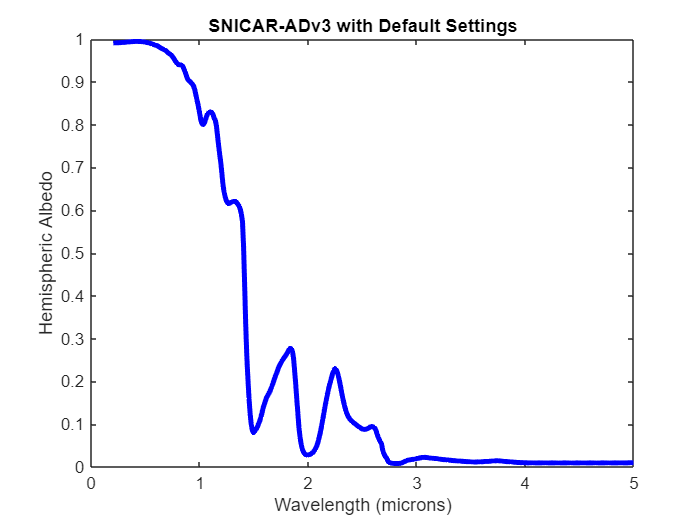

figure
plot(results1.wvl, results1.albedo,...
     'LineWidth',3,...
     'Color','blue')
title('SNICAR-ADv3 with Default Settings')
xlabel('Wavelength (microns)')
ylabel('Hemispheric Albedo')

### Example #2

There are *many* settings that you can modify when running the model by using name-value pair input arguments. The documentation for `snicar.m` can be printed using the `help` function, which includes a full list of the name-value pairs:

help snicar

 SNICARv3 (Flanner et al., 2021)
    A user-friendly version of the snicarAD_v3 function
 
 Syntax
  results = snicar(Name=Value)
 
  where
   Name=Value :: Input arguments given as name-value pairs
   results    :: Struct object containing the model results. See
                 results.README for details on each field in the struct.
 
 Example
  >> results = snicar(SZA=30,...
                      AtmosphereType=6,...
                      SnowpackDensity=400,...
                      SnowGrainRadius=500,...
                      AlbedoGround=0.55,...
                      BlackCarbon=5.0,...
                      Dust=[2.1 6.9 3.4 0.9 0.1],...
                      DustType=3);
                      
 
 Name-Value Pairs (default values shown first)
  NAME                    VALUE
  'IncidentRadiation'     1=direct beam (cle

Let's adjust a few of these settings and compare them with the results of Example 1. For example:

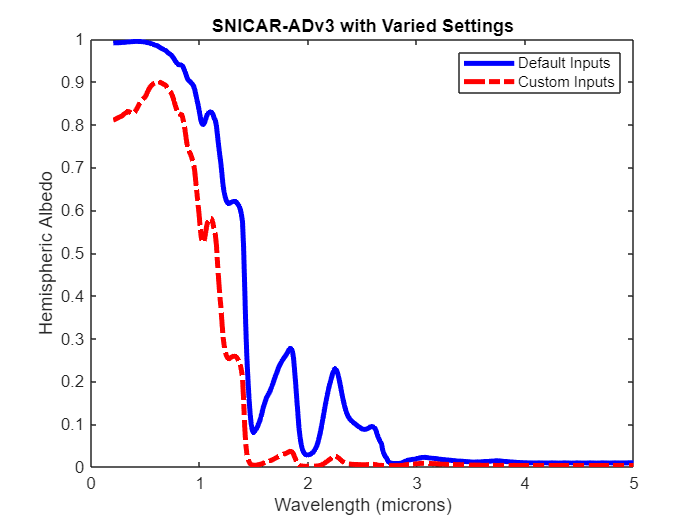

results2 = snicar(SolarZenithAngle=30,...
                  AtmosphereType=6,...
                  SnowpackDensity=400,...
                  SnowGrainRadius=500,...
                  AlbedoGround=0.55,...
                  BlackCarbon=5.0,...
                  Dust=[2.1 6.9 3.4 0.9 0.1],...
                  DustType=3);
figure
plot(results1.wvl, results1.albedo, 'LineWidth', 3, 'Color', 'blue')
hold on
  plot(results2.wvl, results2.albedo, 'LineWidth', 3, 'Color','red', 'LineStyle', '-.')
hold off
title('SNICAR-ADv3 with Varied Settings')
xlabel('Wavelength (microns)')
ylabel('Hemispheric Albedo')
legend('Default Inputs','Custom Inputs')

### Example #3

What if you want to visualize a change in broadband albedo over time? For example, let's say you drill an ice core and you measure the average black carbon concentration over the last 10 years. You can use a `for` loop to adjust the model iteratively and save the broadband albedos over the full 10 years. For example:

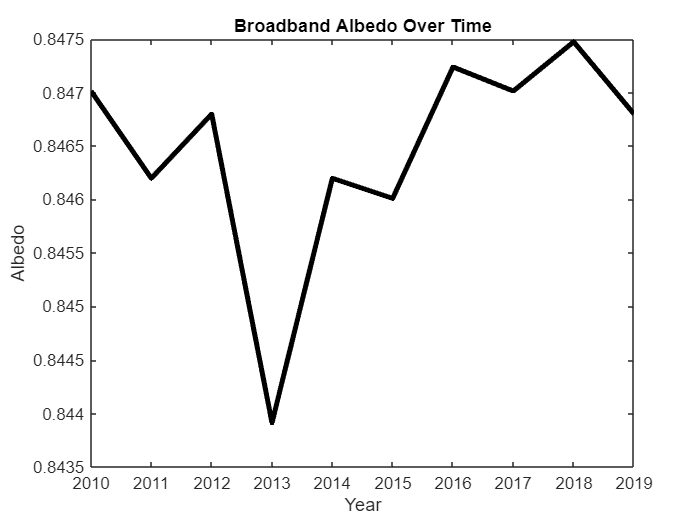

% Define time series data
time = 2010:2019; % Years
BC = [5 9 6 23 9 10 4 5 3 6]; % Black carbon, ppb
AST = [2.1 2.3 1.4 2.0 2.4 2.5 2.6 2.2 2.1 2.5]; % Annual snowpack thicknesses, meters
ASD = [300 330 400 280 300 310 320 290 300 310]; % Annual snowpack density, kg/m3

% Preallocate memory
albedos = zeros(length(time),1);

% Loop through time series data
for year = 1:length(time)
  results3 = snicar(BlackCarbon=BC(year),...
                    SnowpackThickness=AST(year),...
                    SnowpackDensity=ASD(year));
  albedos(year) = results3.alb_slr;
end

% Visualize results
figure
plot(time, albedos, 'LineWidth', 3, 'Color', 'black')
title('Broadband Albedo Over Time')
xlabel('Year')
ylabel('Albedo')

# `SNICARv3.mlapp`

A user-friendly graphical user interface (GUI) that mimics the SNICAR-ADv3 Online Tool ([http://snow.engin.umich.edu/](http://snow.engin.umich.edu/)). 

Opening the GUI in MATLAB is as simple as executing a single line from the Command Window:

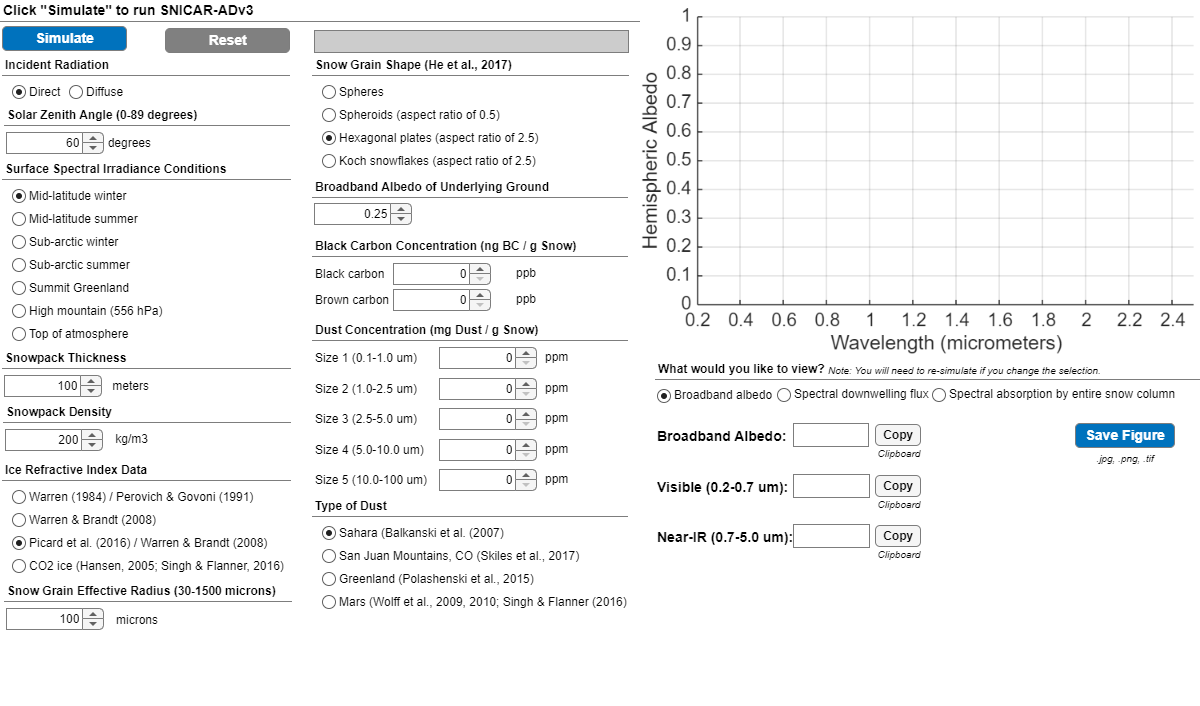

SNICARv3

That's it!  The current version of the GUI provides support for most model inputs, and allows the user to view and save albedo spectra and also copy the albedo estimations.

Please note that when saving figures the spectral output will be saved in the user's current folder, and the name of the file will take the form of `SNICAR_######.####.ext` where the number represents the time and date during which the figure was saved and the file extension is either `jpg`, `png`, or `tif`, depending on which extension the user chose at the time of saving. The time and date are determined by the base function `now()` which returns the date as a serial number. The units of the serial number are "days since midnight on January 1st, Year 0 (Common Era)".